clear;clc;

## 读取数据

load("PointFangXing.mat")
PAB = [-0.176,-0.06,0.6];
P_bound1 = [-0.142,0.47,0.061];
P_bound2 = [0.57,0.28,0.138];
phi = pi./3;
phi = pi./2 - phi;
shenglunum = 6;
a = 0.015*ones(1,shenglunum);

## 计算平面参数

[PlaneParaOut,TrianglePoints] = planefit4(face3_transformed,face1_transformed,face4_transformed,face2_transformed,BoundPoint1,BoundPoint2);

## 计算管路参数

[Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints,P_bound1,P_bound2)

Pin =    -0.1200
    0.4818
    0.1000


Pout =     0.1397
    0.0312
    0.1001


UPP =     0.3138
    0.7318
    0.1004


b = 1.0013

h = 1.0006

w = 0.5206

Tao =     0.4993
   -0.8665
    0.0001


PP =    -0.5538   -0.5537   -0.2935   -0.2934    0.3138    0.5728    0.3138    0.5729
    0.2319    0.2319   -0.2188   -0.2190    0.7318    0.2814    0.7317    0.2812
    0.5999   -0.4007    0.5997   -0.4003    0.6012    0.6010   -0.4004   -0.4001


## 计算相对高度

Ti = ShengDaoGaoDu(shenglunum);

## 计算AB点

toff = [-a./tan(phi),a./tan(phi)];
[PointTable_A_off,PointTable_B_off] = Calculat_JuXing_A_and_B_Points_after_Offest(Tao,UPP,Pin,b,h,PAB,phi,shenglunum,Ti,toff)

PointTable_A_off =    -0.1720   -0.0544    0.1288    0.3357    0.5188    0.6364    0.3730    0.2554    0.0722   -0.1347   -0.3179   -0.4354
   -0.3615   -0.2937   -0.1881   -0.0689    0.0366    0.1044    0.5599    0.4922    0.3866    0.2674    0.1619    0.0941
   -0.4009   -0.4008   -0.4007   -0.4005   -0.4003   -0.4002    0.6010    0.6009    0.6008    0.6006    0.6004    0.6003


PointTable_B_off =    -0.1728   -0.0552    0.1280    0.3349    0.5181    0.6356    0.3737    0.2562    0.0730   -0.1339   -0.3171   -0.4347
   -0.3618   -0.2940   -0.1884   -0.0692    0.0363    0.1041    0.5602    0.4925    0.3869    0.2677    0.1622    0.0944
    0.6003    0.6005    0.6006    0.6008    0.6010    0.6011   -0.4002   -0.4004   -0.4005   -0.4007   -0.4009   -0.4010


## 验证

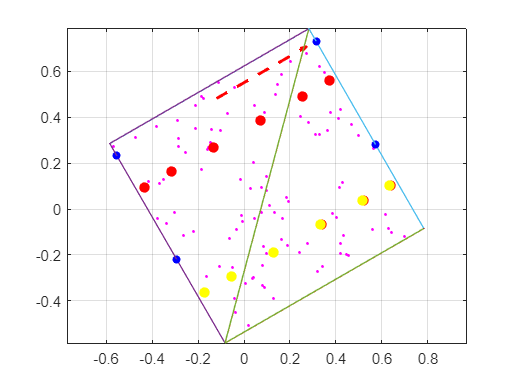

figure
hold on
box on
grid on
axis equal
scatter3(face2_transformed(1, :), face2_transformed(2, :), face2_transformed(3, :), 'm.');
plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]))
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]))
plot3(TrianglePoints(1,[7:9,7]),TrianglePoints(2,[7:9,7]),TrianglePoints(3,[7:9,7]))
plot3(TrianglePoints(1,[10:12,10]),TrianglePoints(2,[10:12,10]),TrianglePoints(3,[10:12,10]))
plot3(TrianglePoints(1,[13:15,13]),TrianglePoints(2,[13:15,13]),TrianglePoints(3,[13:15,13]))
plot3(TrianglePoints(1,[16:18,16]),TrianglePoints(2,[16:18,16]),TrianglePoints(3,[16:18,16]))
plot3(TrianglePoints(1,[19:21,19]),TrianglePoints(2,[19:21,19]),TrianglePoints(3,[19:21,19]))
plot3(TrianglePoints(1,[22:24,22]),TrianglePoints(2,[22:24,22]),TrianglePoints(3,[22:24,22]))
PP = PP';
scatter3(PP(1,1),PP(1,2),PP(1,3),30,'filled','blue')
scatter3(PP(2,1),PP(2,2),PP(2,3),30,'filled','blue')
scatter3(PP(3,1),PP(3,2),PP(3,3),30,'filled','blue')
scatter3(PP(4,1),PP(4,2),PP(4,3),30,'filled','blue')
scatter3(PP(5,1),PP(5,2),PP(5,3),30,'filled','blue')
scatter3(PP(6,1),PP(6,2),PP(6,3),30,'filled','blue')
scatter3(PP(7,1),PP(7,2),PP(7,3),30,'filled','blue')
scatter3(PP(8,1),PP(8,2),PP(8,3),30,'filled','blue')
quiver3(Pin(1),Pin(2),Pin(3),UPP(1)-Pin(1),UPP(2)-Pin(2),UPP(3)-Pin(3),'--r','LineWidth',2.0)

scatter3(PointTable_A_off(1,:),PointTable_A_off(2,:),PointTable_A_off(3,:),50,'filled','red')
scatter3(PointTable_B_off(1,:),PointTable_B_off(2,:),PointTable_B_off(3,:),50,'filled','yellow')